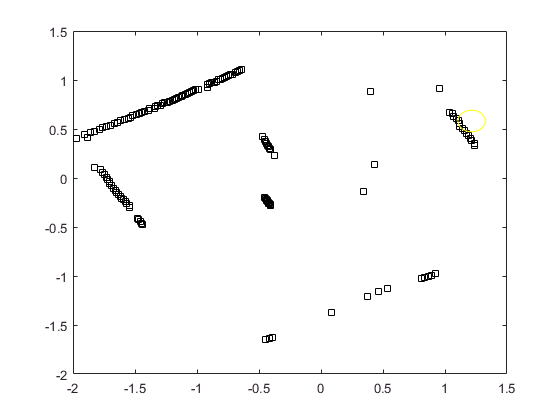

n = 50;
radius = .11;
neato = [-1.5, 0];
inliers = 4;
d = .01;
max = 15;
data = sortrows(data);
ex = round(length(data) / 15);
cutoff = length(data) - ex;
plot(data(:,1), data(:,2), 'ks');
for index = 1:n
    index1 = randi(length(data));
    while data(index1,1) < data(cutoff,1)
        index1 = randi(length(data));
    end
    index2 = randi(length(data));
    while norm(data(index2, :) - data(index1, :)) > radius*2
        index2 = randi(length(data));
    end

    point1 = data(index1, :);
    point2 = data(index2, :);

    circle1 = circle(point1, radius);
    circle2 = circle(point2, radius);
    
    [xout,yout] = circcirc(point1(1),point1(2),radius,point2(1), point2(2),radius);
    intersect = [xout', yout'];
    
    quotecenter = intersect - neato; 
    qc1 = norm(quotecenter(1,:));
    qc2 = norm(quotecenter(2,:));
    
    if qc1 > qc2
        center = intersect(1,:);
    else
        center = intersect(2,:);
    end
    
    distance = sqrt(sum((data - center).^2,2)) - radius;
    new_inlier = length(find(abs(distance) < d));
    
    if new_inlier > inliers && new_inlier < max 
        inliers = new_inlier;
        b1 = circle1;
        b2 = circle2;
        inter = intersect;
        bestcircle = circle(center, radius);
        hold on
        plot(bestcircle(:,1), bestcircle(:,2), 'y');
        hold off
    end     
end

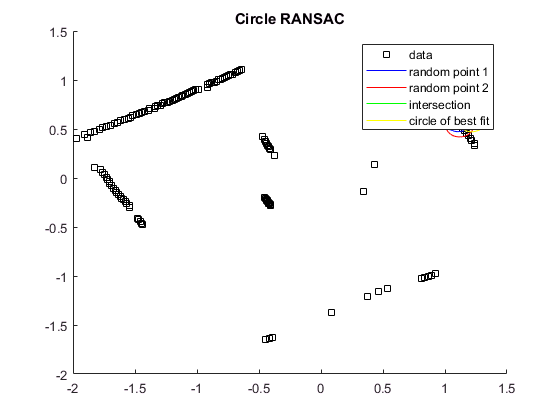

figure
hold on
plot(data(:,1), data(:,2), 'ks');
plot(b1(:, 1), b1(:, 2), 'b');
plot(b2(:, 1), b2(:, 2), 'r');
plot(inter(:,1), inter(:,2), 'g');
plot(bestcircle(:,1), bestcircle(:,2), 'y');
title('Circle RANSAC');
legend('data', 'random point 1', 'random point 2', 'intersection', 'circle of best fit');

function cir = circle(point,r)
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + point(1);
    yunit = r * sin(th) + point(2);
    cir = [xunit' yunit'];
end